%Cargamos los parametros de la camara despues de obtenerlos de la sesion de
%calibracion
ld = load("cameraParams.mat");
intrinsics = ld.cameraParams.Intrinsics;

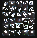

%Cargamos las imagenes que tenemos en la carpeta de de donde estan las fotos con 
% sus respectivas poses y decimos cuantas poses fueron en total 
%(esta es igual al numero de fotos)
numPoses = 30; %CAMBIA
imds = imageDatastore("COBOTPOSES");
montage(imds)

squareSize = 0.022; % Measured in meters
camExtrinsics(numPoses,1) = rigidtform3d;

% Estimate transform from the board to the camera for each pose.
%Estimamos la transoformada del tablero hacia la camara para cada pose
for i = 1:numPoses

    % Undistort the image using the estimated camera intrinsics.
    calibrationImage = readimage(imds,i);
    undistortedImage = undistortImage(calibrationImage,intrinsics);

    % Estimate the extrinsics while disabling the partial checkerboard
    % detections to ensure consistent checkerboard origin across poses. 
    [imagePoints, boardSize] = detectCheckerboardPoints(undistortedImage,PartialDetections=false);
    worldPoints = patternWorldPoints("checkerboard",boardSize,squareSize);
    camExtrinsics(i) = estimateExtrinsics(imagePoints,worldPoints,intrinsics);
end

%Cargamos los datos y tabla que contiene las configuraciones de las juntas
%para cada foto
jointConfiguration = load("jntconfig.mat");
jointPositionsDeg = jointConfiguration.TablaDatos;
jointPositionsDeg = table2array(jointPositionsDeg);

%Cargamos el modelo del robot al que queremos aplicar la configuracion
robotModel = loadrobot("universalUR5e");
robotModel.DataFormat = "column";

endEffectorToBaseTform(numPoses,1) = rigidtform3d;
for i = 1:numPoses
    jointPositionsRad = deg2rad(jointPositionsDeg(i,:))'; % Convert the pose angles from degrees to radians.
    endEffectorToBaseTform(i) = getTransform(robotModel,jointPositionsRad,"flange");
end

%Estima la transformada de la camara con respecto al efector final
config = "moving-camera";
cameraToEndEffectorTform = estimateCameraRobotTransform(camExtrinsics,endEffectorToBaseTform,config)

cameraToEndEffectorTform =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0203 0.0047 0.0419]
                 R: [3×3 double]

                 A: [ 0.0004    0.4958    0.8684    0.0203
                     -0.9999    0.0120   -0.0064    0.0047
                     -0.0136   -0.8684    0.4958    0.0419
                           0         0         0    1.0000]
